# MPC Assignment 1 - Alireza Amiri

## 1

### 1.1

#### 1.1.1

% Step 1: Find the intersections of the lines
% Solve pairs of equations symbolically for intersections
syms x1 x2

% Line equations:
eq1 = x1 + 2*x2 == 8;          % From x1 + 2*x2 = 8
eq2 = 3*x1 + 2*x2 == 12;       % From 3*x1 + 2*x2 = 12
eq3 = x1 + x2 == 4;            % From x1 + x2 = 4

% Solve intersections
% Intersection of eq1 and eq2
sol_1_2 = solve([eq1, eq2], [x1, x2]);

% Intersection of eq1 and eq3
sol_1_3 = solve([eq1, eq3], [x1, x2]);

% Intersection of eq2 and eq3
sol_2_3 = solve([eq2, eq3], [x1, x2]);

% Step 2: Identify intercepts with axes
% x1 intercepts and x2 intercepts
intercept_x1 = solve(eq1, x1);   % x1-intercept of x1 + 2*x2 = 8
intercept_x2 = solve(eq2, x1);   % x1-intercept of 3*x1 + 2*x2 = 12

% Boundary points on axes
boundary_points = [0, 8/2; 4, 0]; % Intersections with axes: (0, 8/2), (4, 0)

% Collect all intersection points
points = [
    double([sol_1_2.x1, sol_1_2.x2]);  % Intersection of eq1 and eq2
    double([sol_1_3.x1, sol_1_3.x2]);  % Intersection of eq1 and eq3
    double([sol_2_3.x1, sol_2_3.x2]);  % Intersection of eq2 and eq3
    boundary_points                     % Intersection with axes
];

% Step 3: Objective function
f = @(x1, x2) 5*x1 + 6*x2;

% Evaluate the objective function at each point
f_vals = arrayfun(@(i) f(points(i, 1), points(i, 2)), 1:size(points, 1));

% Find the minimum value and corresponding point
[min_val, min_idx] = min(f_vals);
optimal_point = points(min_idx, :);

% Display the results
fprintf('Intersection points and corresponding function values:\n');

Intersection points and corresponding function values:


for i = 1:size(points, 1)
    fprintf('Point (x1 = %.2f, x2 = %.2f), f(x1, x2) = %.2f\n', points(i, 1), points(i, 2), f_vals(i));
end

Point (x1 = 2.00, x2 = 3.00), f(x1, x2) = 28.00
Point (x1 = 0.00, x2 = 4.00), f(x1, x2) = 24.00
Point (x1 = 4.00, x2 = 0.00), f(x1, x2) = 20.00
Point (x1 = 0.00, x2 = 4.00), f(x1, x2) = 24.00
Point (x1 = 4.00, x2 = 0.00), f(x1, x2) = 20.00


fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', optimal_point(1), optimal_point(2), min_val);

Optimal point: (x1 = 4.00, x2 = 0.00), Minimum f(x1, x2) = 20.00


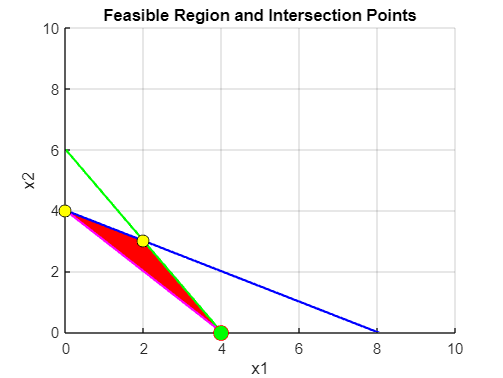


% Step 4: Plot the feasible region and the intersection points
figure; hold on;

% Plot the feasible region
contourf(X1, X2, feasible_region, [1 1], 'FaceColor', 'r', 'EdgeColor', 'none');

% Plot the lines representing the inequalities
plot(x1_vals, (8 - x1_vals)/2, 'b', 'LineWidth', 1.5);     % x1 + 2*x2 = 8
plot(x1_vals, (12 - 3*x1_vals)/2, 'g', 'LineWidth', 1.5);  % 3*x1 + 2*x2 = 12
plot(x1_vals, 4 - x1_vals, 'm', 'LineWidth', 1.5);         % x1 + x2 = 4

% Plot intersection points
plot(points(:, 1), points(:, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);

% Highlight the optimal point
plot(optimal_point(1), optimal_point(2), 'ro', 'MarkerFaceColor', 'g', 'MarkerSize', 10);

% Add labels and title
xlabel('x1');
ylabel('x2');
title('Feasible Region and Intersection Points');
grid on;
hold off;

xlim([0 10])
ylim([0 10])

#### 1.1.2: Using Yalmip

yalmip('clear')
x1 = sdpvar(1,1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1


x2 = sdpvar(1,1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1



constraints = [x1<=8-2*x2 , 3*x1 + 2*x2<= 12, x1 + x2>=4 , x1>=0 , x2 >=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                    Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 1x1|              1 to 8|
|   #2|   Element-wise inequality 1x1|             2 to 12|
|   #3|   Element-wise inequality 1x1|              1 to 4|
|   #4|   Element-wise inequality 1x1|              1 to 1|
|   #5|   Element-wise inequality 1x1|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



obj = 5*x1 + 6*x2

Linear scalar (real, 2 variables)
Coefficients range: 5 to 6



sol = optimize(constraints , obj)

Optimal solution found.



sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '9.13.0.2166757 (R2022b) Update 4'
       yalmiptime: 0.0452
       solvertime: 0.0068
             info: 'Successfully solved (LINPROG)'
          problem: 0



if sol.problem ==0
    val1 = value(x1)
    val2 = value(x2)
    objvalue = value(obj)
end

val1 = 4.0000

val2 = 0

objvalue = 20.0000

#### 1.1.3: Using CVX

cvx_begin

variables x1 x2

% Objective function
minimize(5*x1 + 6*x2)

% Subject to the constraints
subject to
    x1 + 2*x2 <= 8
    3*x1 + 2*x2 <= 12
    x1 + x2 >= 4
    x1 >= 0
    x2 >= 0

cvx_end

% Display the results
x1_value = x1
x2_value = x2

### 1.2

#### 1.2.1: Anlaytical

% Clear previous variables
clear; clc;

% Step 1: Define symbolic variables
syms x1 x2;

% Step 2: Define the constraints
% Lines based on constraints
eq1 = x1 + x2 == -20;  % From x1 + x2 = -20
eq2 = x1 + x2 == 5;    % From x1 + x2 = 5

% Step 3: Solve intersections
% Intersection of eq1 and eq2
sol_1_2 = solve([eq1, eq2], [x1, x2]);

% Define boundaries for x1 and x2
boundary_x1 = [-5, 5];  % x1 boundaries
boundary_x2 = [-1, 5];  % x2 boundaries

% Collect boundary points based on the constraints
boundary_points = [
    -5, -1;   % Bottom left corner
    -5, 5;    % Top left corner
    5, -1;    % Bottom right corner
    0, 5;     % Top right corner
    5,0
];

% Collect all intersection points (if valid)
points = [
    double([sol_1_2.x1, sol_1_2.x2]);  % Intersection of eq1 and eq2
    boundary_points                     % Intersections with axes
];

% Step 4: Define the objective function
f = @(x1, x2) abs(x1 - 5) + abs(x2 - 5);

% Step 5: Evaluate the objective function at each point
% Filter valid points based on constraints
valid_points = points((points(:,1) >= boundary_x1(1)) & (points(:,1) <= boundary_x1(2)) & ...
                      (points(:,2) >= boundary_x2(1)) & (points(:,2) <= boundary_x2(2)), :);

f_vals = arrayfun(@(i) f(valid_points(i, 1), valid_points(i, 2)), 1:size(valid_points, 1));

% Step 6: Find the minimum value and corresponding point
[min_val, min_idx] = min(f_vals);
optimal_point = valid_points(min_idx, :);

% Display the results
fprintf('Valid points and corresponding function values:\n');

Valid points and corresponding function values:


for i = 1:size(valid_points, 1)
    fprintf('Point (x1 = %.2f, x2 = %.2f), f(x1, x2) = %.2f\n', valid_points(i, 1), valid_points(i, 2), f_vals(i));
end

Point (x1 = -5.00, x2 = -1.00), f(x1, x2) = 16.00
Point (x1 = -5.00, x2 = 5.00), f(x1, x2) = 10.00
Point (x1 = 5.00, x2 = -1.00), f(x1, x2) = 6.00
Point (x1 = 0.00, x2 = 5.00), f(x1, x2) = 5.00
Point (x1 = 5.00, x2 = 0.00), f(x1, x2) = 5.00


fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', optimal_point(1), optimal_point(2), min_val);

Optimal point: (x1 = 0.00, x2 = 5.00), Minimum f(x1, x2) = 5.00


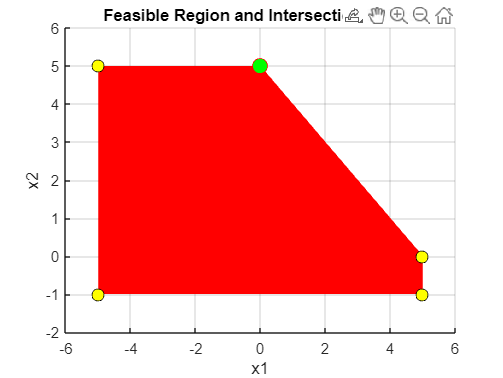


% Step 7: Plot the feasible region and the intersection points
figure; hold on;

% Create a grid for plotting feasible region
[x1_vals, x2_vals] = meshgrid(-5:0.1:5, -1:0.1:5);
feasible_region = (x1_vals + x2_vals >= -20) & (x1_vals + x2_vals <= 5 & ...
                  (-5 <= x1_vals) & (x1_vals <= 5) & (-1 <= x2_vals) & (x2_vals <= 5));

% Plot the feasible region
contourf(x1_vals, x2_vals, feasible_region, [1 1], 'FaceColor', 'r', 'EdgeColor', 'none');

% Plot the constraint lines
plot(x1_vals, -20 - x1_vals, 'k', 'LineWidth', 1.5); % x1 + x2 = -20
plot(x1_vals, 5 - x1_vals, 'k', 'LineWidth', 1.5);   % x1 + x2 = 5

% Plot intersection points
plot(valid_points(:, 1), valid_points(:, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);

% Highlight the optimal point
plot(optimal_point(1), optimal_point(2), 'ro', 'MarkerFaceColor', 'g', 'MarkerSize', 10);

% Add labels and title
xlabel('x1');
ylabel('x2');
title('Feasible Region and Intersection Points');
grid on;
hold off;

% Set axis limits
xlim([-6 6]);
ylim([-2 6]);

#### 1.2.2: Yalmip

% Clear previous variables
clear; clc;

% Step 1: Define the variables
x1 = sdpvar(1,1);  % Decision variable x1
x2 = sdpvar(1,1);  % Decision variable x2

% Step 2: Define the objective function
objective = abs(x1 - 5) + abs(x2 - 5);

% Step 3: Define the constraints
constraints = [
    -5 <= x1 <= 5,      % Constraint for x1
    -1 <= x2 <= 5,      % Constraint for x2
    -20 <= x1 + x2 <= 5 % Constraint for the sum of x1 and x2
];

% Step 4: Solve the optimization problem
options = sdpsettings('verbose', 1);  % Set verbosity to see solver output
sol = optimize(constraints, objective, options);

Optimal solution found.




% Step 5: Check the results
if sol.problem == 0
    % If no error, display the results
    optimal_x1 = value(x1);
    optimal_x2 = value(x2);
    optimal_value = value(objective);

    fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', ...
        optimal_x1, optimal_x2, optimal_value);
else
    % If there was an error, display the error message
    disp('Solver encountered an issue:');
    disp(sol.info);
end

Optimal point: (x1 = 5.00, x2 = 0.00), Minimum f(x1, x2) = 5.00


#### 1.2.3: CVX

% Clear previous variables
clear; clc;

% Step 1: Start CVX
cvx_begin

    % Step 2: Define the variables
    variables x1 x2;  % Decision variables x1 and x2

    % Step 3: Define the objective function
    minimize(abs(x1 - 5) + abs(x2 - 5));

    % Step 4: Define the constraints
    subject to
        -5 <= x1 <= 5;      % Constraint for x1
        -1 <= x2 <= 5;      % Constraint for x2
        -20 <= x1 + x2 <= 5; % Constraint for the sum of x1 and x2

cvx_end

 
Calling SDPT3 4.0: 10 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  4,   num. of socp blk  =  2
 dim. of linear var  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e-01|1.9e+00|1.5e+03| 4.100000e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.783|1.000|5.3e-02|1.1e-02|2.8e+02| 2.235904e+02 -4.906071e+01| 0:0:00| chol  1  1 
 2|0.932|0.954|3.6e-03|1.2e-02|1.9e+01| 5.515023e+00 -1.274188e+01| 0:0:00| chol  1  1 
 3|1.000|0.768|2.4e-07|3.6e-03|7.4e+00


% Step 5: Display the results
fprintf('Optimal point: (x1 = %.2f, x2 = %.2f), Minimum f(x1, x2) = %.2f\n', x1, x2, abs(x1 - 5) + abs(x2 - 5));

Optimal point: (x1 = 2.32, x2 = 2.68), Minimum f(x1, x2) = 5.00


### 2.1


yalmip('clear')

% Define variables
x1 = sdpvar(1,1);
x2 = sdpvar(1,1);

% Define objective function
objective = (x1 - 1)^2 + (x2 - 2.5)^2;

% Define constraints
constraints = [x1 - 2*x2 >= -2, ...
               -x1 - 2*x2 >= -6, ...
               -x1 + x2 >= -2, ...
               x1 >= 0, x2 >= 0];

% Solve problem
optimize(constraints, objective)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '9.13.0.2166757 (R2022b) Update 4'
       yalmiptime: 0.1134
       solvertime: 0.0356
             info: 'Successfully solved (Successfully solved (QUADPROG))'
          problem: 0



% Display solution
val1 = value(x1)

val1 = 1.4000

val2 = value(x2)

val2 = 1.7000

objvalue = value(objective)

objvalue = 0.8000


disp(['Optimal x1: ', num2str(solution_x1)])

Unrecognized function or variable 'solution_x1'.

disp(['Optimal x2: ', num2str(solution_x2)])
disp(['Optimal objective value: ', num2str(solution_obj)])

cvx_begin
    variables x1 x2
    % Objective function
    minimize((x1 - 1)^2 + (x2 - 2.5)^2)

    % Constraints
    subject to
        x1 - 2*x2 >= -2
        -x1 - 2*x2 >= -6
        -x1 + x2 >= -2
        x1 >= 0
        x2 >= 0
cvx_end

 
Calling SDPT3 4.0: 11 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of sdp    var  =  4,   num. of sdp  blk  =  2
 dim. of linear var  =  5
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.8e+00|3.8e+00|9.0e+02| 7.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|3.7e-06|4.1e-02|8.4e+01| 6.212644e+01 -1.663679e+01| 0:0:00| chol  1  1 
 2|0.903|0.985|1.4e-07|4.6e-03|6.9e+00| 4.066391e+00 -2.716047e+00| 0:0:00| chol  1  1 
 3|0.656|1.000|4.6e-07|4.1e-04|4.2e+00


% Display solution
disp(['Optimal x1: ', num2str(x1)])

Optimal x1: 1.4


disp(['Optimal x2: ', num2str(x2)])

Optimal x2: 1.7


disp(['Optimal objective value: ', num2str(cvx_optval)])

Optimal objective value: 0.8


## 3.

### 3.1

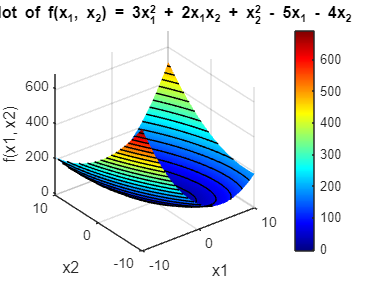

% Clear workspace
clear; clc;

% Define the function as a symbolic expression
syms x1 x2;
f = 3*x1^2 + 2*x1*x2 + x2^2 - 5*x1 - 4*x2;

% Create a mesh grid for x1 and x2 values
[x1_vals, x2_vals] = meshgrid(-10:0.5:10, -10:0.5:10);

% Evaluate the function on the grid
f_vals = 3*x1_vals.^2 + 2*x1_vals.*x2_vals + x2_vals.^2 - 5*x1_vals - 4*x2_vals;

% Plot the surface
figure;
surf(x1_vals, x2_vals, f_vals);  % Create a 3D surface plot
shading interp;                  % Interpolates shading to make it smooth
colormap jet;                    % Set color map
colorbar;                        % Show color scale

% Label axes and title
xlabel('x1');
ylabel('x2');
zlabel('f(x1, x2)');
title('3D Plot of f(x_1, x_2) = 3x_1^2 + 2x_1x_2 + x_2^2 - 5x_1 - 4x_2');

% Highlight the convexity behavior
hold on;
contour3(x1_vals, x2_vals, f_vals, 20, 'k');  % Add contour lines to the surface
hold off;

### 3.2: Yalmip

% Clear workspace
clear; clc;

% Define variables
x = sdpvar(2,1);

% Define the objective function
f = 3*x(1)^2 + 2*x(1)*x(2) + x(2)^2 - 5*x(1) - 4*x(2);

% Set up the optimization problem
optimize([], f);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Display the results
xval = value(x)

xval =     0.2500
    1.7500


objval = value(f)

objval = -4.1250


% fprintf('Optimal x1 = %.4f, Optimal x2 = %.4f\n', optimal_x(1), optimal_x(2));
% fprintf('Minimum value of the function: %.4f\n', optimal_fval);

### 3.3: CVX

% Clear workspace and previous CVX problem
clear; clc;
cvx_clear;

% Use CVX for solving the optimization problem
cvx_begin

    variables x1 x2
    % Define the objective function
    f = 3*x1^2 + 2*x1*x2 + x2^2 - 5*x1 - 4*x2;

Error using  .* 
Disciplined convex programming error:
    Invalid quadratic form(s): not a square.


Error in  *  (line 36)
    z = feval( oper, x, y );

    
    % Use 'minimize' function for the objective
    minimize(f)
cvx_end

% Display the results
fprintf('Optimal x1 = %.4f, Optimal x2 = %.4f\n', x1, x2);
fprintf('Minimum value of the function: %.4f\n', f);

### 3.4

% Clear workspace
clear; clc;

% Define variables
x = sdpvar(2,1);

% Define the objective function (negated for maximization)
f = -(3*x(1)^2 + 2*x(1)*x(2) + x(2)^2 - 5*x(1) - 4*x(2));

% Set up the optimization problem
optimize([], f);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    0.000e+00    5.000e+00
    1       2   -1.720000e+02    0.000e+00    4.300e+01    6.403e+00
    2       3   -2.796176e+05    0.000e+00    1.788e+03    2.804e+02
    3       4   -1.095274e+10    0.000e+00    3.545e+05    5.659e+04
    4       5   -1.063951e+16    0.000e+00    3.494e+08    5.600e+07
    5       6   -2.579618e+23    0.000e+00    1.720e+12    2.759e+11

Problem appears unbounded.

fmincon stopped because the objective function value is less than
the value of the objective function limit and constraints 
are satisfied to within the value of the constraint tolerance.

<<a href


% Display the results (negated back)
optimal_x = value(x);
optimal_fval = -value(f); % negate the function value back

fprintf('Optimal x1 = %.4f, Optimal x2 = %.4f\n', optimal_x(1), optimal_x(2));

Optimal x1 = -243236479749.1021, Optimal x2 = -130439567620.7782


fprintf('Maximum value of the function: %.4f\n', optimal_fval);

Maximum value of the function: 257961758541185663631360.0000


% Clear workspace
clear; clc;

% Use CVX for solving the maximization problem
cvx_begin

    variables x1 x2
    % Define the objective function (negated for maximization)
    f = -(3*x1^2 + 2*x1*x2 + x2^2 - 5*x1 - 4*x2);

Error using  .* 
Disciplined convex programming error:
    Invalid quadratic form(s): not a square.


Error in  *  (line 36)
    z = feval( oper, x, y );

    minimize(f)
cvx_end

% Display the results (negated back)
fprintf('Optimal x1 = %.4f, Optimal x2 = %.4f\n', x1, x2);
fprintf('Maximum value of the function: %.4f\n', -f); % negate the function value back

% Clear workspace
clear; clc;

% Define variables
x1 = sdpvar(1,1);
x2 = sdpvar(1,1);

% Define the objective function
obj = sqrt(sqrt((x1 - x2^2)^2 + 0.02)) + 0.01*x2^2;

% Define any constraints (if applicable)
constraints = [];

% Set options for solver
options = sdpsettings('solver', 'fmincon', 'verbose', 1);

% Solve the problem
sol = optimize(constraints, obj, options)

sol = struct with fields:
    solvertime: 0
       problem: 14
          info: 'Model creation failed (<a href="yalmip.github.io/inside/debuggingcreationfailed">learn to debug</a>)(See https://yalmip.github.io/squareroots/)'
    yalmiptime: 0.0270



% Check if the solution was successful
if sol.problem == 0
    % Display the results
    disp('Optimal solution found:');
    disp('x1 =');
    disp(value(x1));
    disp('x2 =');
    disp(value(x2));
    disp('Objective value =');
    disp(value(obj));
else
    disp('Failed to find a solution');
    disp(sol.info);
end

Failed to find a solution


Model creation failed (<a href="yalmip.github.io/inside/debuggingcreationfailed">learn to debug</a>)(See https://yalmip.github.io/squareroots/)


% Clear workspace
clear; clc;

% CVX optimization
cvx_begin

    variables x1 x2
    % Define the objective function
    minimize( sqrt(sqrt((x1 - x2^2)^2 + 0.02)) + 0.01*x2^2 )

Error using cvx/pow_cvx
Disciplined convex programming error:
    Illegal operation: {concave} .^ {2}
    (Consider POW_P, POW_POS, or POW_ABS instead.)

Error in  .^  (line 55)
    z = pow_cvx( x, y, 'power' );

Error in  ^  (line 9)
    z = power( x, y );

cvx_end

% Display the results
disp('Optimal solution found:');
disp('x1 =');
disp(x1);
disp('x2 =');
disp(x2);
disp('Objective value =');
disp(cvx_optval);


Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          0.4142           3.806        0
    2              147          0.4142           3.026        1
    3              194          0.4029           2.023        0
    4              241          0.4029           1.357        1
    5              288          0.4029           1.221        2
    6              335          0.3989          0.8975        0
    7              382           0.385          0.7295        0
    8              429           0.385          0.7836        1
    9              476           0.385          0.7186        2
   10              523           0.385          0.5768        3
   11      

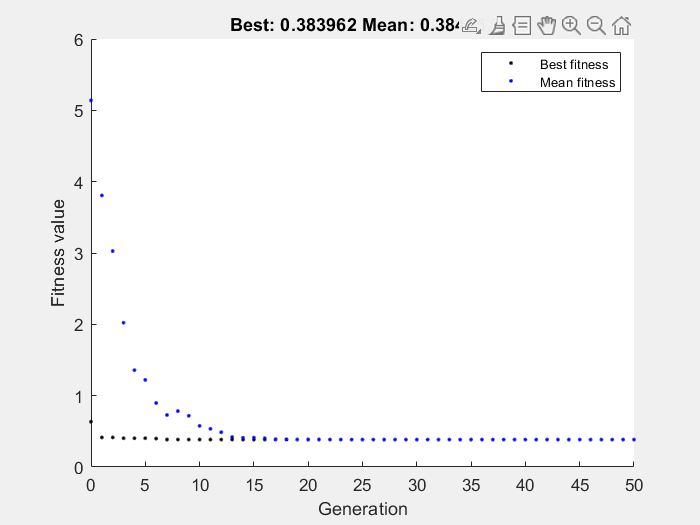

% Clear workspace
clear; clc;

% Define the objective function
obj = @(x) sqrt(sqrt((x(1) - x(2)^2)^2 + 0.02)) + 0.01*x(2)^2;

% Define the bounds for x1 and x2 (if any)
lb = [-10, -10];  % Lower bounds for x1 and x2
ub = [10, 10];    % Upper bounds for x1 and x2

% Set options for the genetic algorithm solver
options = optimoptions('ga', 'Display', 'iter', 'MaxGenerations', 50, 'PlotFcn', @gaplotbestf);

% Run the genetic algorithm
[x_opt, fval, exitflag, output] = ga(obj, 2, [], [], [], [], lb, ub, [], options);


% Display the results
fprintf('Optimal solution found using Genetic Algorithm:\n');

Optimal solution found using Genetic Algorithm:


fprintf('x1 = %.4f\n', x_opt(1));

x1 = 0.7904


fprintf('x2 = %.4f\n', x_opt(2));

x2 = -0.8889


fprintf('Objective value = %.4f\n', fval);

Objective value = 0.3840


% Clear workspace
clear; clc; rng(1);  % For reproducibility

% Step 1: Define the noisy Rastrigin function (Objective function)
obj = @(x) (10*2 + (x(1)^2 - 10*cos(2*pi*x(1))) + (x(2)^2 - 10*cos(2*pi*x(2)))) + randn()*0.1;

% Step 2: Set parameters for the Cross-Entropy method
n_samples = 100;        % Number of samples per iteration
n_elite = 100;           % Number of elite samples
n_iterations = 100;     % Maximum number of iterations
mu = [0, 0];            % Initial mean of the Gaussian distribution (centered at origin)
sigma = [5, 5];         % Initial standard deviation (spread of the Gaussian)
alpha = 0.7;            % Learning rate for updating the mean and variance

% Step 3: Initialize variables to store the best solution
best_solution = [];
best_fval = inf;

% Step 4: Start the Cross-Entropy optimization loop
for iter = 1:n_iterations
    % Sample solutions from the Gaussian distribution
    samples = mvnrnd(mu, diag(sigma), n_samples);
    
    % Evaluate the objective function for each sample
    fvals = arrayfun(@(i) obj(samples(i, :)), 1:n_samples);
    
    % Sort the samples by their objective values and select the elite set
    [sorted_fvals, idx] = sort(fvals);
    elite_samples = samples(idx(1:n_elite), :);
    
    % Update the mean and standard deviation based on the elite samples
    new_mu = mean(elite_samples);
    new_sigma = std(elite_samples);
    
    % Apply the learning rate to update the distribution parameters
    mu = alpha * mu + (1 - alpha) * new_mu;
    sigma = alpha * sigma + (1 - alpha) * new_sigma;
    
    % Check if the best solution has improved
    if sorted_fvals(1) < best_fval
        best_fval = sorted_fvals(1);
        best_solution = elite_samples(1, :);
    end
    
    % Display progress
    fprintf('Iteration %d: Best Objective Value = %.4f\n', iter, best_fval);
end

Iteration 1: Best Objective Value = 2.6016
Iteration 2: Best Objective Value = 1.9008
Iteration 3: Best Objective Value = 1.9008
Iteration 4: Best Objective Value = 1.9008
Iteration 5: Best Objective Value = 1.9008
Iteration 6: Best Objective Value = 1.9008
Iteration 7: Best Objective Value = 1.9008
Iteration 8: Best Objective Value = 1.9008
Iteration 9: Best Objective Value = 1.9008
Iteration 10: Best Objective Value = 1.9008
Iteration 11: Best Objective Value = 0.1127
Iteration 12: Best Objective Value = 0.1127
Iteration 13: Best Objective Value = 0.1127
Iteration 14: Best Objective Value = 0.1127
Iteration 15: Best Objective Value = 0.1127
Iteration 16: Best Objective Value = 0.1127
Iteration 17: Best Objective Value = 0.1127
Iteration 18: Best Objective Value = 0.1127
Iteration 19: Best Objective Value = 0.1127
Iteration 20: Best Objective Value = 0.1127
Iteration 21: Best Objective Value = 0.1127
Iteration 22: Best Objective Value = 0.1127
Iteration 23: Best Objective Value = 0.11


% Step 5: Display final result
fprintf('Best solution found: x1 = %.4f, x2 = %.4f\n', best_solution(1), best_solution(2));

Best solution found: x1 = -0.0033, x2 = -0.0151


fprintf('Best objective value: f(x1, x2) = %.4f\n', best_fval);

Best objective value: f(x1, x2) = 0.0768


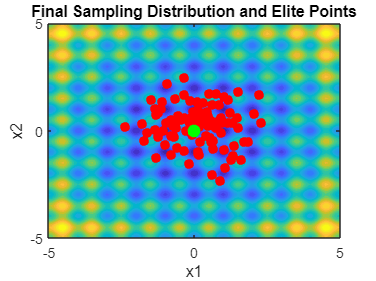


% Step 6: Plot the final distribution and elite points
figure;
[x1_vals, x2_vals] = meshgrid(-5:0.1:5, -5:0.1:5);
f_vals = arrayfun(@(x1, x2) obj([x1, x2]), x1_vals, x2_vals);
contourf(x1_vals, x2_vals, f_vals, 20, 'LineColor', 'none');
hold on;
plot(samples(:, 1), samples(:, 2), 'ko', 'MarkerSize', 4);
plot(elite_samples(:, 1), elite_samples(:, 2), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
plot(best_solution(1), best_solution(2), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
xlabel('x1');
ylabel('x2');
title('Final Sampling Distribution and Elite Points');
hold off;